# Loading the dataset

clear; clc;

digitDatasetPath = fullfile(matlabroot, 'toolbox', 'nnet', 'nndemos', ...
    'nndatasets', 'DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

# Example image

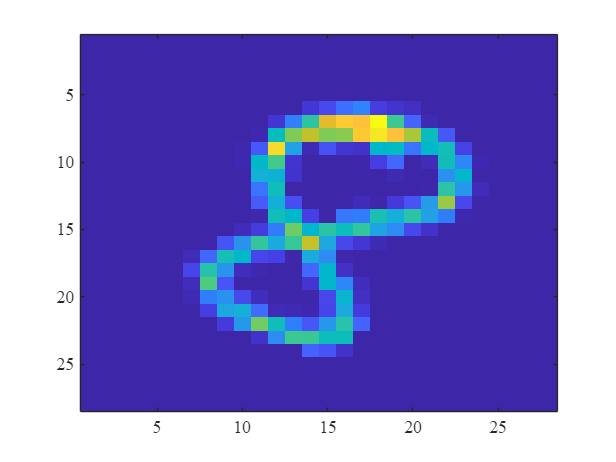

img = readimage(imds, randi(10000));

figure;
imagesc(img)

# Converting the data to imgs

imgs = zeros(10000, 28, 28);

for i = 1:10000
    imgs(i, :, :) = readimage(imds, i);  
end

imgs_reshaped = reshape(imgs, [10000, 28*28]);


digits_list = 1:9;

data =[];
labels = [];
for digit = digits_list
    idx = (1:1000) + digit*1000;
    data = [data; imgs_reshaped(idx, :)];
    labels = [labels; imds.Labels(idx)];
end

tsne_score = tsne(data);


% Plot
figure;
cmap = turbo(length(digits_list)); cmap = repelem(cmap, 1000, 1);

scatter(tsne_score(:, 1), tsne_score(:, 2), 10, cmap, 'filled');


colormap(cmap);

cb = colorbar();
cb.Ticks = (0.5:length(digits_list)-0.5)/length(digits_list);
cb.TickLabels = digits_list;

% cb.TickLabels(cb.Ticks, digits_list);  % Show actual digit labels

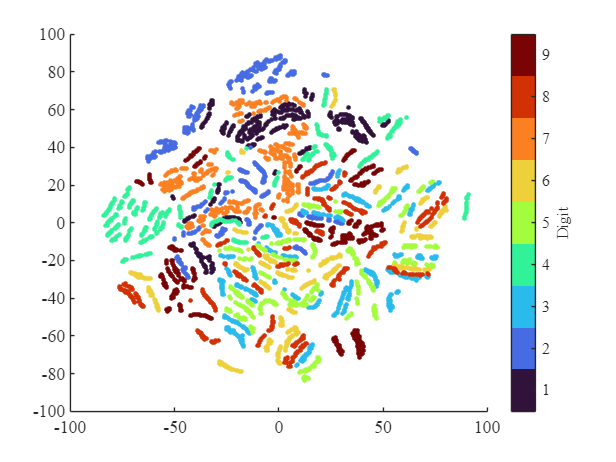

cb.Label.String = 'Digit';

[coeff,score,latent,tsquared,explained,mu] = pca()